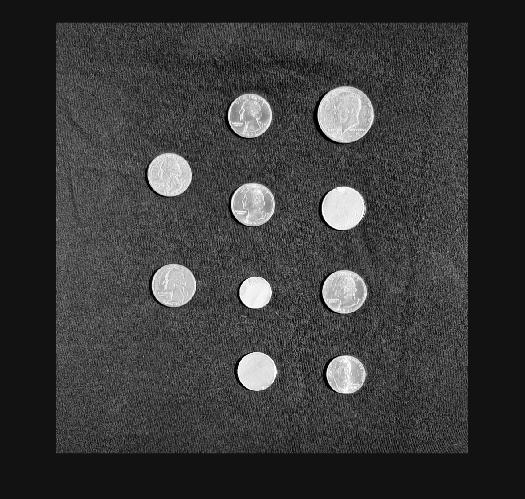

testImageIdx = randi ([1,3]);
testCoinImage = imread("testCoinImage"+ testImageIdx + ".png");
figure, imshow(testCoinImage);

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 02-Jan-2025
%----------------------------------------------------


% Find circles
[centers,radii,~] = imfindcircles(X,[25 75],'ObjectPolarity','bright','Sensitivity',0.85);
max_num_circles = Inf;
if max_num_circles < length(radii)
    centers = centers(1:max_num_circles,:);
    radii = radii(1:max_num_circles);
end
BW = circles2mask(centers,radii,size(X,1:2));

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end

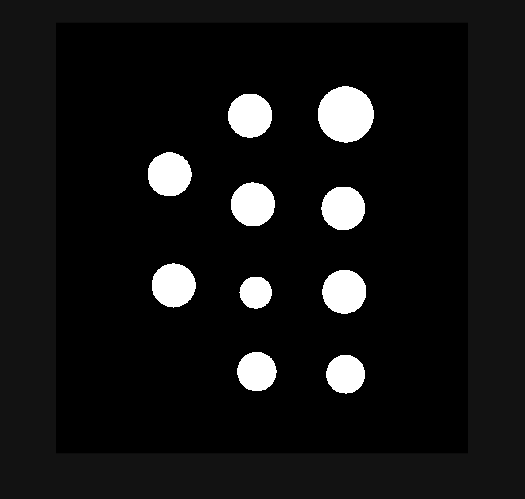

testCoinMask = segmentImage(testCoinImage);
imshow(testCoinMask);

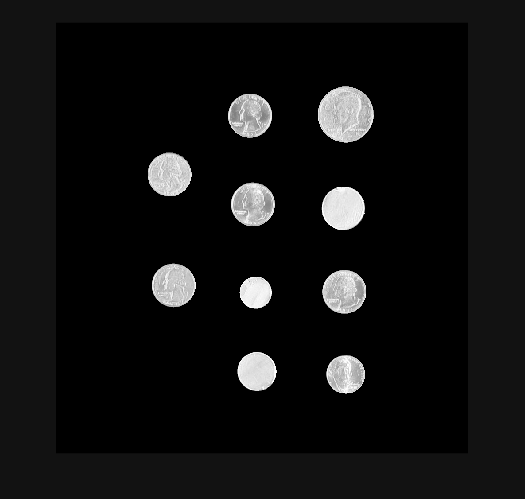

maskedImg = testCoinImage;
maskedImg(repmat(~testCoinMask, [1, 1])) = 0;
imshow(maskedImg);

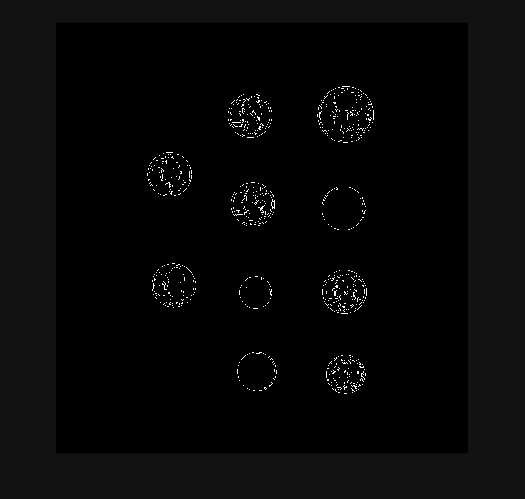

%faceEdgeMask = edge(maskedImg, "canny", [0.01, 0.1]);
faceEdgeMask = edge(maskedImg, "sobel");
imshow(faceEdgeMask);

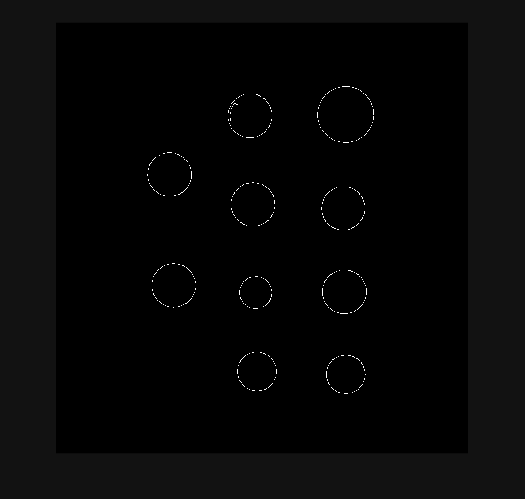

edgeonly = edge(maskedImg, "canny", [0.1, 0.32]);
imshow(edgeonly);

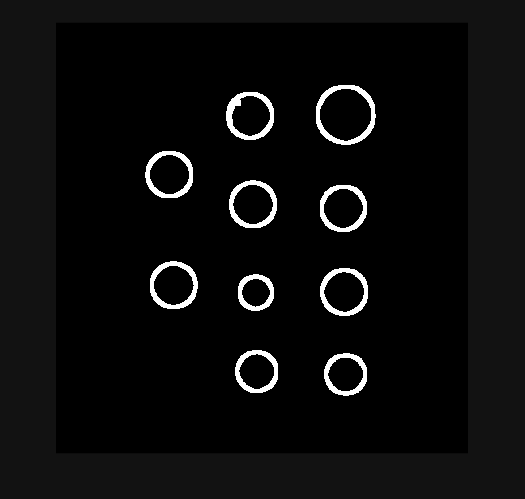

se = strel('square',9);
edgeonly = imdilate(edgeonly, se);
imshow(edgeonly);

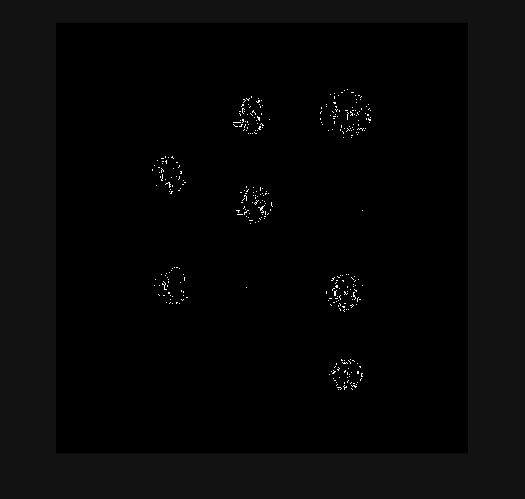

validOnly = faceEdgeMask & ~edgeonly;
imshow(validOnly);

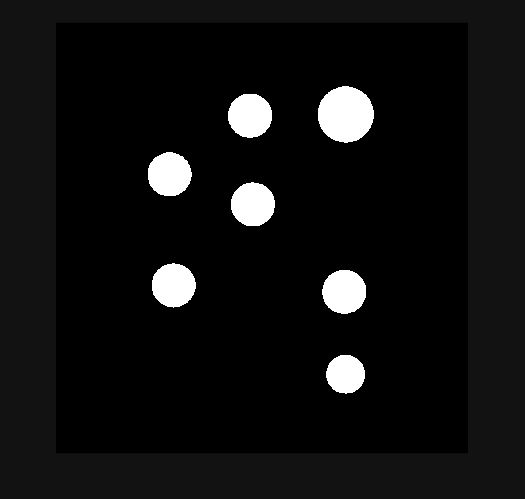

se2 = strel("square", 30);
validClean = imclose(validOnly, se2);
se3 = strel("square", 6);
validClean = imerode(validClean, se3);
seDisk = strel("disk", 32);
validCoinMask = imdilate(validClean, seDisk);
validCoinMask = validCoinMask & testCoinMask;
imshow(validCoinMask);